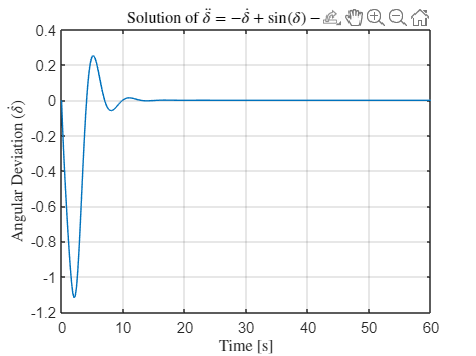

set(0,'defaultTextInterpreter','latex');
% Define the parameters
M = 1;    % Replace with your actual values
D = 1;
B = 1;
G = 1;

% Define the initial conditions
y1_0 = 0; % Initial position
y2_0 = 0; % Initial velocity

% Create a function to represent the system of ODEs
ode_system = @(t, y) [y(2); (-D*y(2) + B*sin(y(1)) - G*cos(y(1))) / M];

% Define the time span
tspan = [0, 60]; % Adjust the time span as needed

% Solve the ODE using ode45
[t, Y] = ode45(ode_system, tspan, [y1_0, y2_0]);

% Extract the solution
y1_solution = Y(:, 1); % x(t)
y2_solution = Y(:, 2); % x'(t)

% Plot the results
plot(t, y2_solution);
xlabel('Time [s]');
ylabel('Angular Deviation ($\dot{\delta}$)');
title('Solution of $ \ddot{\delta} = - \dot{\delta} + \sin(\delta) - \cos(\delta)$');
grid on;

% Define the parameters
M = 1;    % Replace with your actual values
D = 1;
B = 1;
G = 1;

% Create a function to represent the system of ODEs
ode_system = @(t, y) [y(2); (-D*y(2) + B*sin(y(1)) - G*cos(y(1))) / M];

% Generate a grid of initial conditions
[x1, x2] = meshgrid(-pi:0.2:pi, -2:0.2:2);
y1_dot = x2;
y2_dot = (-D*x2 + B*sin(x1) - G*cos(x1)) / M;

% Normalize the vectors for plotting
y1_dot_norm = y1_dot ./ sqrt(y1_dot.^2 + y2_dot.^2);
y2_dot_norm = y2_dot ./ sqrt(y1_dot.^2 + y2_dot.^2);

% Create a phase portrait
quiver(x1, x2, y1_dot_norm, y2_dot_norm);
xlabel('Position (x)');
ylabel('Velocity (x'')');
title('Phase Portrait of M*x'' = -D*x'' + B*sin(x) - G*cos(x)');
axis tight;
grid on;

% Define the parameters
M = 1;    % Replace with your actual values
D = 1;
B = 1;
G = 1;

% Create a function to represent the system of ODEs
ode_system = @(t, y) [y(2); (-D*y(2) + B*sin(y(1)) - G*cos(y(1))) / M];

% Define a range of initial conditions
initial_conditions = 0;  % Adjust as needed

% Initialize arrays to store the trajectories
x_trajectories = [];
x_dot_trajectories = [];

% Solve the ODE for each set of initial conditions
for y1_0 = initial_conditions
    y2_0 = 0;  % You can choose an initial velocity if desired
    tspan = [0, 10]; % Adjust the time span as needed

    [t, Y] = ode45(ode_system, tspan, [y1_0, y2_0]);

    % Extract the solutions
    y1_solution = Y(:, 1); % x(t)
    y2_solution = Y(:, 2); % x'(t)

    % Append the trajectories
    x_trajectories = [x_trajectories; y1_solution];
    x_dot_trajectories = [x_dot_trajectories; y2_solution];
end

% Plot the parametric curves
figure;
plot(x_trajectories, x_dot_trajectories);
xlabel('Position (x)');
ylabel('Velocity (x'')');
title('Parametric Plot of M*x'' = -D*x'' + B*sin(x) - G*cos(x)');
grid on;

